# Schroer-Ott targeting for the lifted standard map

This Live Script rebuilds the corrected Schroer-Ott workflow from the computational pieces rather than calling `main_schroer_ott_targeting`.

The state space used here is the lifted cylinder S^1 x R: x is periodic modulo one, while y is never wrapped. Controls are instantaneous vertical y-kicks with `u` <= 0.003. The operational targeting method uses small proxy balls around direct-hyperbolic unstable periodic orbits (UPOs), then chooses switching iterates by minimizing the remaining resolved transfer time to the next proxy or final target.

Stable and unstable manifolds are diagnostic overlays. They are not used as a complete explicit polygonal pass network.

clear; close all; clc;
projectFolder = fileparts(mfilename('fullpath'));
restoredefaultpath;
rehash toolboxcache;
addpath(projectFolder);
fprintf('Project folder: %s\n', projectFolder);

Project folder: C:\Users\npcoz\AppData\Local\Temp\Editor_fyknw


fprintf('MATLAB version: %s\n', version);

MATLAB version: 26.1.0.3276743 (R2026a) Update 3


## Authoritative implementation and file inventory

Only this folder is placed on the MATLAB path. The nested backup/copy folder is deliberately not added to the path. The inventory table below is generated from the files that MATLAB can see in this authoritative folder.

authoritativeFolder = projectFolder;
authoritativeFunctions = {
    'schroer_ott_default_config'
    'so_standard_map_lifted'
    'so_standard_map_inverse_lifted'
    'so_jacobian'
    'so_jacobian_product'
    'so_enumerate_periodic_orbits'
    'so_construct_first_light_route'
    'so_resolve_connection'
    'so_multistage_targeting'
    'so_replay_stage'
    'so_plot_results'
    };
calledFiles = strings(numel(authoritativeFunctions), 1);
for k = 1:numel(authoritativeFunctions)
    calledFiles(k) = string(which(authoritativeFunctions{k}));
end
calledFileTable = table(string(authoritativeFunctions), calledFiles, ...
    'VariableNames', {'functionName','resolvedPath'})

calledFileTable = 11×2 table
              functionName                                                                    resolvedPath                                                      
    ________________________________    ________________________________________________________________________________________________________________________

    "schroer_ott_default_config"        "C:\Users\npcoz\OneDrive - Imperial College London\Project\Codes\schroer_ott_targeting\schroer_ott_default_config.m"    
    "so_standard_map_lifted"            "C:\Users\npcoz\OneDrive - Imperial College London\Project\Codes\schroer_ott_targeting\so_standard_map_lifted.m"        
    "so_standard_map_inverse_lifted"    "C:\Users\npcoz\OneDrive - Imperial College London\Project\Codes\schroer_ott_targeting\so_standard_map_inverse_lifted.m"
    "so_jacobian"                       "C:\Users\npcoz\OneDrive - Imperial College London\Projec


inventory = local_file_inventory(projectFolder)

inventory = 4×4 table
                          name                                                folder                         bytes        lastModified    
    _________________________________________________    ________________________________________________    _____    ____________________

    "LiveEditorEvaluationHelperEeditor4666E0C3motw.m"    "C:\Users\npcoz\AppData\Local\Temp\Editor_fyknw"    25686    22-Aug-2026 01:50:51
    "LiveEditorEvaluationHelperEeditor6469E901motw.m"    "C:\Users\npcoz\AppData\Local\Temp\Editor_fyknw"    11731    22-Aug-2026 02:16:35
    "LiveEditorEvaluationHelperEeditor987727B4motw.m"    "C:\Users\npcoz\AppData\Local\Temp\Editor_fyknw"    25541    22-Aug-2026 01:59:10
    "LiveEditorEvaluationHelperEeditorD4A23A69motw.m"    "C:\Users\npcoz\AppData\Local\Temp\Editor_fyknw"        1    22-Aug-2026 01:48:12


## Mathematical and numerical configuration

The corrected deterministic first-light case is not the paper Figure-3 geometry. It is a nondegenerate development case at k=1.25. Its source centre is outside every retained proxy ball and remains outside those balls under every admissible zero-time vertical control.

The route bracket has a declared margin and open boundaries. This avoids accepting or rejecting a resonance merely because a rectangle centre is equal to a nominal rotation number to round-off precision.

cfg = schroer_ott_default_config();
cfg.saveFigures = true;
if ~exist(cfg.outputDirectory, 'dir'); mkdir(cfg.outputDirectory); end
if ~exist(cfg.figureDirectory, 'dir'); mkdir(cfg.figureDirectory); end
configurationTable = local_configuration_table(cfg)

configurationTable = 16×2 table
                quantity                                 value                 
    _________________________________    ______________________________________

    "k"                                  "1.25"                                
    "controlAmplitude"                   "0.003"                               
    "sourceX"                            "[0.859409, 0.909409]"                
    "sourceY"                            "[0.486716, 0.526716]"                
    "targetX"                            "[0.210000, 0.250000]"                
    "targetY"                            "[0.720000, 0.760000]"                
    "maxForwardIterations"               "8"                                   
    "maxBackwardIterations"              "6"                                   
    "maxTotalTransferTime"               "14"                                  
    "proxyTargetRad

## Standard map, inverse map, Jacobian, and control segment

The lifted standard map is

The cylinder version wraps only x. The inverse map is checked by applying the forward map followed by the inverse map. The Jacobian determinant is one, so the map is area-preserving in the lifted variables.

zCheck = [0.31; 0.44];
zForward = so_standard_map_lifted(zCheck, cfg);
zBack = so_standard_map_inverse_lifted(zForward, cfg);
J = so_jacobian(zCheck, cfg);
h = 1e-7;
Jfd = [(so_standard_map_lifted(zCheck + [h; 0], cfg) - so_standard_map_lifted(zCheck - [h; 0], cfg)) / (2*h), ...
       (so_standard_map_lifted(zCheck + [0; h], cfg) - so_standard_map_lifted(zCheck - [0; h], cfg)) / (2*h)];
mapValidationTable = table( ...
    norm(zBack - zCheck), ...
    det(J), ...
    norm(J - Jfd), ...
    cfg.controlAmplitude, ...
    2*cfg.controlAmplitude, ...
    'VariableNames', {'forwardInverseError','jacobianDeterminant','jacobianFiniteDifferenceError','uMax','delta'})

mapValidationTable = 1×5 table
    forwardInverseError    jacobianDeterminant    jacobianFiniteDifferenceError    uMax     delta
    ___________________    ___________________    _____________________________    _____    _____

        7.8505e-17                  1                      5.8746e-10              0.003    0.006


## UPO enumeration

Periodic chains are solved using fixed-(p,m) Newton equations in the lifted map,

Multiple distinct chains with the same (p,m) are retained. Lower-period duplicates are rejected, and cyclic/cylindrical deduplication prevents repeated copies of the same chain. Stability is classified from the trace of the monodromy matrix.

catalogue = so_enumerate_periodic_orbits(cfg);
upoCatalogue = catalogue.byOmega

upoCatalogue = 18×12 table
        id         period    winding     omega      trace     residue     absResidue     residual     averageY    averageYError       classification       samePMCount
    ___________    ______    _______    _______    _______    ________    __________    __________    ________    _____________    ____________________    ___________

    "chain-012"      5          1           0.2    -7.4731      2.3683      2.3683      3.2398e-16        0.2               0      "inverse-hyperbolic"         2     
    "chain-011"      5          1           0.2     11.895     

retainedDirectHyperbolic = catalogue.byOmega(catalogue.byOmega.classification == "direct-hyperbolic", :)

retainedDirectHyperbolic = 9×12 table
        id         period    winding     omega     trace     residue     absResidue     residual     averageY    averageYError      classification       samePMCount
    ___________    ______    _______    _______    ______    ________    __________    __________    ________    _____________    ___________________    ___________

    "chain-011"      5          1           0.2    11.895     -2.4737      2.4737      1.2686e-14        0.2      3.1641e-15      "direct-hyperbolic"         2     
    "chain-007"      4          1          0.25    6.3029 

diagnosticFractions = catalogue.diagnosticFractions

diagnosticFractions = 7×3 table
     omega     represented    directHyperbolic
    _______    ___________    ________________

       0.25       true             true       
    0.33333       true             true       
        0.4       true             true       
        0.5       true             true       
        0.6       true             true       
    0.66667       true             true       
       0.75       true             true       


maximumAverageYError = max(catalogue.byOmega.averageYError)

maximumAverageYError = 1.8818e-14

## Route construction and source-to-proxy audit

The route is chosen algorithmically from direct-hyperbolic chains whose rotation numbers fall inside the declared source-target y bracket. No chain identifier is hard-coded into the route.

The audit table explicitly checks the corrected nondegeneracy condition: the source starts outside all initial proxy balls, and the entire admissible zero-time control segment also stays outside them.

route = so_construct_first_light_route(catalogue, cfg);
routeTable = local_route_table(route)

routeTable = 2×6 table
      chainID       omega     period    winding      classification       componentCount
    ___________    _______    ______    _______    ___________________    ______________

    "chain-016"        0.6      5          3       "direct-hyperbolic"          5       
    "chain-005"    0.66667      3          2       "direct-hyperbolic"          3       


sourceProxyAudit = so_source_proxy_audit(cfg, route);
sourceProxyAudit.byProxy

ans = 8×11 table
    routeIndex      chainID          componentID         phasePointIndex    proxyX     proxyY     sourceDistance    controlledSegmentDistance    proxyRadius    directAtZeroWithoutControl    directAtZeroWithAdmissibleControl
    __________    ___________    ____________________    _______________    _______    _______    ______________    _________________________    ___________    __________________________    _________________________________

        1         "chain-016"    "chain-016-phase-01"           1           0.66613     0.4958        0.21856                0.21843                0.03        

auditSummary = struct2table(rmfield(sourceProxyAudit, 'byProxy'), 'AsArray', true)

auditSummary = 1×7 table
    sourceState     minimumSourceDistance    minimumControlledSegmentDistance    directContainmentPossibleAtN0    proxyRadius    sourceOutsideAllInitialProxies    controlSegmentOutsideAllInitialProxies
    ____________    _____________________    ________________________________    _____________________________    ___________    ______________________________    ______________________________________

    {2×1 double}          0.055818                       0.055309                            false                   0.03                    true                                  true                  


## Forward-backward connection solver

A connection from a source point to a target component is found by a diagonal search in increasing total time. For each split (n_forward, n_backward), the forward image of the vertical control segment and the backward image of the target boundary are adaptively refined and intersected. Intersections are refined inside their original segment brackets. Direct zero-time containment is treated separately and chooses the admissible control with minimum absolute value.

The first provisional connection below is computed only to expose the connection data before the full multistage solve.

sourceState = so_rectangle_center(cfg.sourceRectangle);
sourceState(1) = so_wrap_x(sourceState(1));
[firstConnection, firstProfile] = so_resolve_connection(sourceState, route.targetComponents{1}, cfg, so_new_performance_profile());
firstConnectionSummary = local_connection_table(firstConnection)

firstConnectionSummary = 1×12 table
    success    nForward    nBackward    totalIterations    controlY    intersectionResidual    directContainment    zeroTimePretest    targetContained    timeMinimumCertified    selectionCertified      targetComponent   
    _______    ________    _________    _______________    ________    ____________________    _________________    _______________    _______________    ____________________    __________________    ____________________

     true         2            0               2              0                 0                    false       

firstProfile

firstProfile = struct with fields:
                       forwardFamilyBuilds: 1
                      backwardFamilyBuilds: 5
                 backwardFamilyCacheReuses: 0
                    indexedCrossingQueries: 29
    exactSegmentTestsAfterSpatialFiltering: 6
                   naiveComparisonsAvoided: 44826
                             jProbesPruned: 0
                            runtimeByStage: []
                       stageRuntimeSeconds: []
                      replayRuntimeSeconds: []
               directContainmentCandidates: 0
                           refinementCalls: 2
                          unresolvedSplits: 0
                     curvePointEvaluations: 0
                       peakCurvePointCount: 450


## Multistage targeting and adaptive switch rule

The full targeting routine first resolves a provisional connection to the current proxy. It then tests each possible switching index j along that planned path. The selected j minimizes

If j=0 is selected, the current proxy is skipped because the calculated route to the next target is no worse than entering the proxy first. The skip is therefore an objective-based decision, not evidence that the source began inside the proxy.

targetingTimer = tic;
result = so_multistage_targeting(cfg, catalogue, route);
result.diagnosticManifolds = so_compute_diagnostic_manifolds(route, cfg);
targetingRuntime = toc(targetingTimer);
fprintf('Corrected deterministic targeting runtime: %.3f seconds\n', targetingRuntime);

Corrected deterministic targeting runtime: 155.339 seconds


stageSummary = so_stage_summary_table(result)

stageSummary = 3×18 table
    stage    targetKind       targetID       rotationNumber    connectionSuccess    nForward    nBackward    tauResolved    controlY       targetComponent       targetPhasePointIndex    intersectionResidual    targetContained    selectedSwitchIndex    skipped    timeMinimumCertified    selectionCertified    resolutionHoles
    _____    __________    ______________    ______________    _________________    ________    _________    ___________    _________    ____________________    ____

switchTable = local_switch_table(result.switchEvaluations)

switchTable = 2×8 table
    stage    currentTargetID     nextTargetID     selectedJ    selectedObjective    selectedFinite    prunedProbeCount    probeCount
    _____    _______________    ______________    _________    _________________    ______________    ________________    __________

      1        "chain-016"      "chain-005"           0               13                true                 0                 3    
      2        "chain-005"      "final-target"        9               23                true                 0                14    


executedControlTable = result.executedControls

executedControlTable = 2×21 table
    stage       targetID       preControlX    preControlY    postControlX    postControlY    switchStateX    switchStateY    controlY     stageIterations    executedIterations    cumulativeIterations    maxPathwiseReplayError    switchStateReplayError    finalStateReplayError    targetContained    replayPassed    controlWithinBound    stateX    stateY     propagationConsistencyError
    _____    ______________    ___________    ___________    ____________    ____________    ____________

## Independent replay of each accepted stage

Each accepted executed segment stores the pre-control state, the instantaneous control, the post-control state, the planned path, the switch/final state, and pathwise replay errors. Replay starts from the stored pre-control state, applies the stored y-kick once, and advances the lifted standard map one step at a time. It does not call the connection solver and does not reconstruct the control.

replayTable = local_replay_table(result)

replayTable = 2×12 table
    segment    preControlX    preControlY    controlY     postControlX    postControlY    iterations    maxPathwiseReplayError    switchStateReplayError    finalStateReplayError    targetContained    replayPassed
    _______    ___________    ___________    _________    ____________    ____________    __________    ______________________    ______________________    _____________________    _______________    ____________

       1         0.88441        0.50672      0.0020939      0.88441         0.50881            9                  0                         

## Controlled trajectory figures

The figures are generated inline. PNG copies are optional, but the important thesis figures are also exported as SVG and EPS in the figure directory. The trajectory figure preserves instantaneous control jumps and inserts NaN breaks across periodic x-boundary jumps.

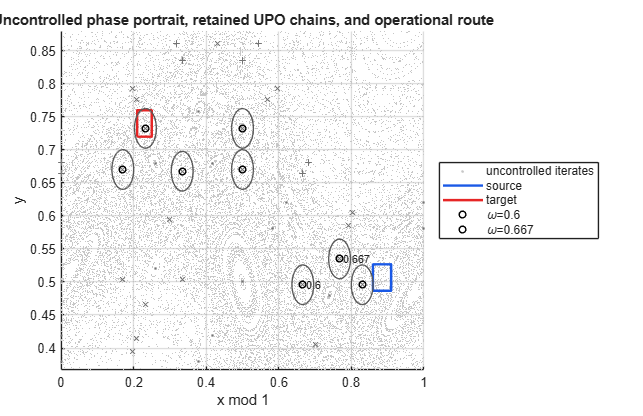

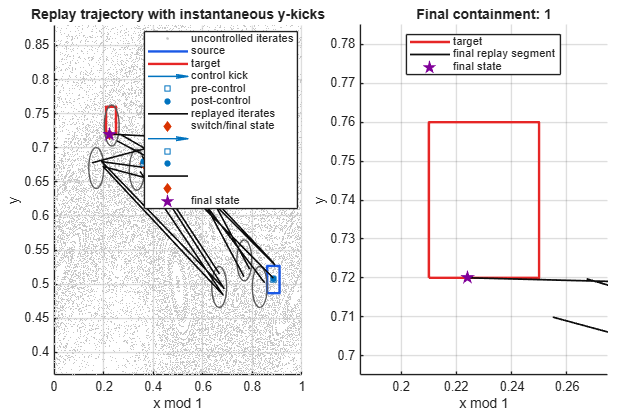

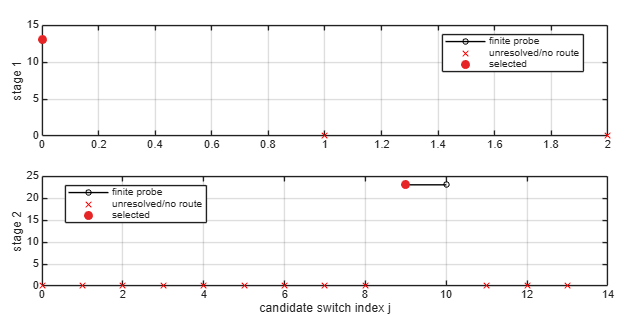

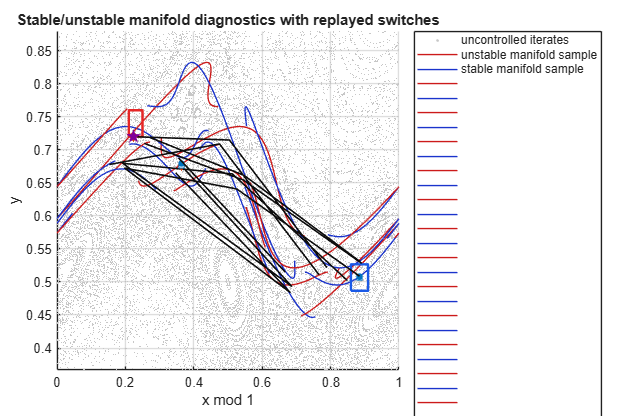

figureHandles = so_plot_results(result);

exportedFigureInventory = local_export_inventory(cfg.figureDirectory)

exportedFigureInventory = 16×2 table
                      name                        bytes   
    ________________________________________    __________

    "controlled_trajectory_replay.svg"          1.9458e+07
    "diagnostic_manifolds_switch_points.svg"    1.9719e+07
    "phase_portrait_route.svg"                  1.9601e+07
    "switch_objectives.svg"                          39082
    "upo_eigendirections.svg"                        77769
    "controlled_trajectory_replay.eps"          1.6091e+06
    "diagnostic_manifolds_switch_points.eps"    1.7888e+06
    "phase_portrait_route.eps"                  1.6627e+06
    "switch_objectives.eps"                           8974
    "upo_eigendirections.eps"                        20130
    "controlled_trajectory.png"                      65457
    "controlled_trajectory_replay.png"          1.8999e+05
    "diagnostic_manifolds_switch_points.png"    2.4743e+05
    "phas

## Uncontrolled propagation from the same source point

The uncontrolled baseline is propagated from the same source centre with no controls. Hitting is checked against the final target rectangle over a declared finite observation horizon.

uncontrolledHorizon = 5000;
uncontrolledComparison = local_uncontrolled_comparison(sourceState, cfg, uncontrolledHorizon)

uncontrolledComparison = 1×5 table
    observationHorizon    reached    hitIteration    lastX      lastY 
    __________________    _______    ____________    ______    _______

           5000            true          1309        375.24    0.73576


## Equation (1) diagnostic

The paper's notation for target size is ambiguous because it refers to a target radius and later to a ball diameter. The code declares the convention in cfg.equationOne.targetSizeConvention. The table also shows the predicted value obtained under the alternative convention. L=1 is labelled as a declared order-one phase-space scale, not a fitted length.

equationOneDiagnostics = result.equationOneDiagnostics

equationOneDiagnostics = 3×18 table
    stage    nForward    nBackward    realisedTau    predictedTau    alternativePredictedTau    delta    epsilon_t    alternativeEpsilon_t    targetSizeConvention    alternativeTargetSizeConvention    L                 LConvention                  lambda1    absLambda2      targetComponent       discrepancyRatio    cornerAmbiguous
    _____    ________    _________    ___________    ____________    _______________________    _____    _________    ____________________    ____________________</

## Corrected validation suite

The tests include independent negative replay checks: corrupting a stored planned path or corrupting a stored control must fail replay. The test names are distinct and no longer call other tests as aliases.

testResults = test_schroer_ott_first_light()

                              name                              passed    message
    ________________________________________________________    ______    _______

    "lifted forward/inverse consistency"                        true        ""   
    "cylinder forward/inverse consistency"                      true        ""   
    "analytic Jacobian versus finite differences"               true        ""   
    "area preservation"                                         true        ""   
    "wrapped-x/lifted-x trajectory consistency"                 true        ""   
    "y remains unwrapped"                                       true        ""   
    "adaptive refinement of folded curve"                       true        ""   
    "midpoint deviation detects hidden fold"                    true        ""   
    "closed-boundary wraparound refinement"                     true        "

testResults = 46×3 table
                           name                           passed    message
    __________________________________________________    ______    _______

    "lifted forward/inverse consistency"                  true        ""   
    "cylinder forward/inverse consistency"                true        ""   
    "analytic Jacobian versus finite differences"         true        ""   
    "area preservation"                                   true        ""   
    "wrapped-x/lifted-x trajectory consistency"           true        ""   
    "y remains unwrapped"                                 true        ""   
    "adaptive refinement of folded curve"                 true        ""   
    "midpoint deviation detects hidden fold"              true        ""   
    "closed-boundary wraparound refinement"               true        ""   
    "indexed intersection versus exh

testSummary = groupsummary(testResults, "passed")

testSummary = 1×2 table
    passed    GroupCount
    ______    __________

    true          46    


## Three-level numerical-resolution study

This compact resolution study is project-specific. It varies only curve and intersection-resolution settings for the corrected deterministic first-light case. It does not change k, source, target, control bound, route policy, or iteration horizons.

resolutionStudy = so_run_resolution_study(true);
resolutionStudy.comparison

ans = 3×21 table
       level       initialControlSamples    initialBoundarySamples    maxGapFraction    midpointToleranceFraction    maxSubdivisionDepth    maxPoints    success    failureCategory      selectedRoute       controls           splits            switchingIndices    totalIterations    maxResidual    maxReplayError    targetContainment    unresolvedSplits    minimumCertified    peakCurvePointCount    runtimeSeconds
    ___________    _____________________    ______________________    ______________    _________________________    ___

## Estimated paper Figure-3 comparison case

The source and target rectangles for the paper comparison are estimated from the rendered Figure 3 axes because the paper does not tabulate their exact coordinates. The seven route rotations are selected from the direct-hyperbolic chains matching the full-width resonances visible in the figure: 1/4, 1/3, 2/5, 1/2, 3/5, 2/3, and 3/4.

The published 125-132 iteration range is reported descriptively. It is not used as an acceptance criterion.

[paperCfg, paperMetadata] = so_paper_comparison_config();
paperMetadata

paperMetadata = struct with fields:
                        source: [1×1 struct]
                        target: [1×1 struct]
            digitisationMethod: "visual reading of rendered Schroer-Ott Figure 3 page against axes"
         coordinateUncertainty: 0.0150
       expectedRotationNumbers: [0.2500 0.3333 0.4000 0.5000 0.6000 0.6667 0.7500]
      publishedControlledRange: [125 132]
    publishedExampleIterations: 125
           maxControlAmplitude: 0.0030


paperCase = so_run_paper_comparison_case(true);
paperComparisonSummary = local_paper_case_table(paperCase)

paperComparisonSummary = 1×5 table
            classification             targetReached    totalIterations    numberOfControls    targetContained
    _______________________________    _____________    _______________    ________________    _______________

    "failed numerical reproduction"        false               0                  0                 false     


## Fifty-source paper-comparison ensemble

The following command runs exactly 50 uniformly sampled source points in the adopted paper-comparison source rectangle. It stores all successes, failures, unresolved cases, exact sampled states, replay errors, and comparison counts relative to the published 125-132 range.

This can be computationally expensive because every trial runs the full forward-backward route independently. It is intentionally not replaced by three hand-picked points.

paperEnsembleFile = fullfile(paperCfg.outputDirectory, 'paper_50_source_ensemble.mat');
runPaperEnsembleNow = exist('RUN_FULL_PAPER_ENSEMBLE', 'var') && RUN_FULL_PAPER_ENSEMBLE;
if runPaperEnsembleNow || ~isfile(paperEnsembleFile)
    paperEnsemble = so_run_paper_ensemble(true);
else
    loadedEnsemble = load(paperEnsembleFile, 'ensemble');
    paperEnsemble = loadedEnsemble.ensemble;
end
paperEnsemble.summary

ans = 1×13 table
    attempts    successes    successFraction    minimum    maximum    mean    median    standardDeviation    interquartileRange    finiteIterationCounts    numberBelow125    numberWithin125To132    numberAbove132
    ________    _________    _______________    _______    _______    ____    ______    _________________    __________________    _____________________    ______________    ____________________    ______________

       50           0               0             NaN        NaN      NaN      NaN             NaN                

paperEnsemble.trials

ans = 50×18 table
    trial    sourceX     sourceY     success        failureCategory                         selectedRoute                    numberOfControls    totalControlledIterations    maxAbsControl    totalAbsControl    maxIntersectionResidual    maxPathwiseReplayError    finalX    finalY    finalContainment    unresolvedSplits    minimumCertified    runtimeSeconds
    _____    _______    _________    _______    ________________________    _____________________________________________    ________________    _________________________    

## One mild-noise demonstration

The deterministic map functions are not changed for noise. Instead, a separate replay wrapper applies the already-computed deterministic control schedule and adds one stored Gaussian y-kick sequence with sigma = 0.01*(2*u_max) = 6e-5. No retargeting is performed.

noiseDemo = so_run_mild_noise_demo(result, true);
noiseSummary = local_noise_table(noiseDemo)

noiseSummary = 1×11 table
    sigma    delta       seed       noisySuccess    totalIterations    maximumControl    storedNoiseReplayError    finalX    finalY     finalContainment    endpointDisplacement
    _____    _____    __________    ____________    _______________    ______________    ______________________    ______    _______    ________________    ____________________

    6e-05    0.006    3.1416e+05       false              23             0.0028557                 0               15.271    0.74475         false                0.05272       


## Final validation summary

The table below collects the main deterministic checks. Paper-comparison and 50-source ensemble outcomes must be interpreted separately because the paper geometry is estimated from a figure, not tabulated.

finalValidationSummary = local_final_validation_table(result, sourceProxyAudit, testResults, resolutionStudy, paperCase, paperEnsemble, noiseDemo)

finalValidationSummary = 13×2 table
                  quantity                                value             
    _____________________________________    _______________________________

    "deterministicTargetReached"             "true"                         
    "sourceOutsideInitialProxies"            "true"                         
    "controlSegmentOutsideInitialProxies"    "true"                         
    "anyPositiveSwitch"                      "true"                         
    "allControlsWithinBound"                 "true"                         
    "maxReplayError"                         "0"                            
    "finalContainment"                       "true"                         
    "testSuitePassed"                        "true"                         
    "resolutionLevelsSucceeded"              "true"                         
    "paperCaseClassification"                "fa

## Local helper functions

function inventory = local_file_inventory(projectFolder)
files = dir(fullfile(projectFolder, '*'));
isRegular = ~[files.isdir].';
files = files(isRegular);
inventory = table(string({files.name}).', string({files.folder}).', [files.bytes].', ...
    datetime([files.datenum].', 'ConvertFrom', 'datenum'), ...
    'VariableNames', {'name','folder','bytes','lastModified'});
inventory = sortrows(inventory, 'name');
end

function tbl = local_configuration_table(cfg)
names = ["k";"controlAmplitude";"sourceX";"sourceY";"targetX";"targetY"; ...
    "maxForwardIterations";"maxBackwardIterations";"maxTotalTransferTime"; ...
    "proxyTargetRadius";"routeBracketMargin";"routeLowerBoundary";"routeUpperBoundary"; ...
    "intersectionBackend";"equationOneTargetSizeConvention";"equationOneLConvention"];
values = [
    string(cfg.k)
    string(cfg.controlAmplitude)
    sprintf('[%.6f, %.6f]', cfg.sourceRectangle.xMin, cfg.sourceRectangle.xMax)
    sprintf('[%.6f, %.6f]', cfg.sourceRectangle.yMin, cfg.sourceRectangle.yMax)
    sprintf('[%.6f, %.6f]', cfg.targetRectangle.xMin, cfg.targetRectangle.xMax)
    sprintf('[%.6f, %.6f]', cfg.targetRectangle.yMin, cfg.targetRectangle.yMax)
    string(cfg.maxForwardIterations)
    string(cfg.maxBackwardIterations)
    string(cfg.maxTotalTransferTime)
    string(cfg.proxyTargetRadius)
    string(cfg.routeBracket.margin)
    string(cfg.routeBracket.lowerBoundary)
    string(cfg.routeBracket.upperBoundary)
    string(cfg.intersectionBackend)
    string(cfg.equationOne.targetSizeConvention)
    string(cfg.equationOne.LConvention)
    ];
tbl = table(names, values, 'VariableNames', {'quantity','value'});
end

function tbl = local_route_table(route)
chainID = string({route.chains.id}).';
omega = [route.chains.omega].';
period = [route.chains.period].';
winding = [route.chains.winding].';
classification = string({route.chains.classification}).';
componentCount = cellfun(@numel, route.targetComponents).';
tbl = table(chainID, omega, period, winding, classification, componentCount);
end

function tbl = local_connection_table(conn)
tbl = table(conn.success, conn.nForward, conn.nBackward, conn.totalIterations, ...
    conn.control, conn.intersectionResidual, conn.directContainment, ...
    conn.zeroTimePretest, conn.targetContained, conn.timeMinimumCertified, ...
    conn.selectionCertified, string(conn.targetComponent), ...
    'VariableNames', {'success','nForward','nBackward','totalIterations','controlY', ...
    'intersectionResidual','directContainment','zeroTimePretest','targetContained', ...
    'timeMinimumCertified','selectionCertified','targetComponent'});
end

function tbl = local_switch_table(switchEvaluations)
rows = {};
for i = 1:numel(switchEvaluations)
    selected = switchEvaluations(i).selected;
    rows(end + 1, :) = {switchEvaluations(i).stage, switchEvaluations(i).currentTargetID, ...
        switchEvaluations(i).nextTargetID, selected.j, selected.objectiveJ, ...
        selected.finite, switchEvaluations(i).pruned, numel(switchEvaluations(i).probes)}; %#ok<AGROW>
end
tbl = cell2table(rows, 'VariableNames', {'stage','currentTargetID','nextTargetID', ...
    'selectedJ','selectedObjective','selectedFinite','prunedProbeCount','probeCount'});
end

function tbl = local_replay_table(result)
rows = {};
for i = 1:numel(result.executionSegments)
    seg = result.executionSegments(i);
    rows(end + 1, :) = {i, seg.preControlState(1), seg.preControlState(2), ...
        seg.control, seg.postControlState(1), seg.postControlState(2), ...
        seg.iterations, seg.maxPathwiseReplayError, seg.switchStateReplayError, ...
        seg.finalStateReplayError, seg.targetContained, seg.replayPassed}; %#ok<AGROW>
end
tbl = cell2table(rows, 'VariableNames', {'segment','preControlX','preControlY', ...
    'controlY','postControlX','postControlY','iterations','maxPathwiseReplayError', ...
    'switchStateReplayError','finalStateReplayError','targetContained','replayPassed'});
end

function exported = local_export_inventory(figureDirectory)
files = [dir(fullfile(figureDirectory, '*.svg')); dir(fullfile(figureDirectory, '*.eps')); ...
    dir(fullfile(figureDirectory, '*.png'))];
if isempty(files)
    exported = table();
else
    exported = table(string({files.name}).', [files.bytes].', ...
        'VariableNames', {'name','bytes'});
end
end

function tbl = local_uncontrolled_comparison(z0, cfg, horizon)
target = so_make_rectangle_component(cfg.targetRectangle, cfg, 'final-target');
z = z0;
hitIteration = NaN;
for n = 1:horizon
    z = so_standard_map_lifted(z, cfg);
    if target.contains(z, cfg.containmentTolerance)
        hitIteration = n;
        break;
    end
end
tbl = table(horizon, ~isnan(hitIteration), hitIteration, z(1), z(2), ...
    'VariableNames', {'observationHorizon','reached','hitIteration','lastX','lastY'});
end

function tbl = local_paper_case_table(paperCase)
if isempty(paperCase.result)
    tbl = table(string(paperCase.classification), false, Inf, 0, false, ...
        'VariableNames', {'classification','targetReached','totalIterations','numberOfControls','targetContained'});
else
    tbl = table(string(paperCase.classification), paperCase.result.targetReached, ...
        paperCase.result.totalExecutedIterations, paperCase.result.numberOfControls, ...
        paperCase.result.targetContained, ...
        'VariableNames', {'classification','targetReached','totalIterations','numberOfControls','targetContained'});
end
end

function tbl = local_noise_table(noiseDemo)
tbl = table(noiseDemo.sigma, noiseDemo.delta, noiseDemo.seed, noiseDemo.noisySuccess, ...
    noiseDemo.totalIterations, noiseDemo.maximumControl, noiseDemo.storedNoiseReplayError, ...
    noiseDemo.finalState(1), noiseDemo.finalState(2), noiseDemo.finalContainment, ...
    noiseDemo.endpointDisplacement, ...
    'VariableNames', {'sigma','delta','seed','noisySuccess','totalIterations', ...
    'maximumControl','storedNoiseReplayError','finalX','finalY','finalContainment', ...
    'endpointDisplacement'});
end

function tbl = local_final_validation_table(result, audit, testResults, resolutionStudy, paperCase, paperEnsemble, noiseDemo)
quantity = [
    "deterministicTargetReached"
    "sourceOutsideInitialProxies"
    "controlSegmentOutsideInitialProxies"
    "anyPositiveSwitch"
    "allControlsWithinBound"
    "maxReplayError"
    "finalContainment"
    "testSuitePassed"
    "resolutionLevelsSucceeded"
    "paperCaseClassification"
    "paperEnsembleAttempts"
    "paperEnsembleSuccesses"
    "noiseStoredReplayError"
    ];
value = [
    string(result.targetReached)
    string(audit.sourceOutsideAllInitialProxies)
    string(audit.controlSegmentOutsideAllInitialProxies)
    string(any(result.executedControls.stageIterations > 0))
    string(all(result.executedControls.controlWithinBound))
    string(max(result.executedControls.maxPathwiseReplayError))
    string(result.targetContained)
    string(all(testResults.passed))
    string(all(resolutionStudy.comparison.success))
    string(paperCase.classification)
    string(paperEnsemble.summary.attempts)
    string(paperEnsemble.summary.successes)
    string(noiseDemo.storedNoiseReplayError)
    ];
tbl = table(quantity, value);
end